# EVALF Test Script

Note that EVALF is currently implemented using double precision floating point values.

#### Test Case 1: Single Community (Node)

We first test EVALF for a single node. We expect to see  characteristic SEIR curves [1]. The total number of individuals in the node should be constant.

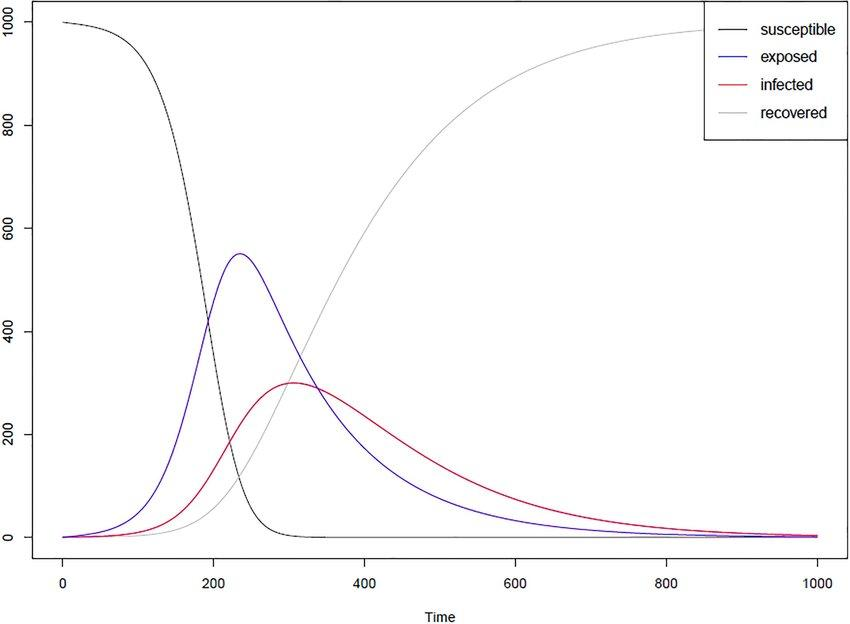

[1]* An open-data-driven agent-based model to simulate infectious disease outbreaks. *December 2018. [PLoS ONE](https://www.researchgate.net/journal/1932-6203_PLoS_ONE) 13(12):e0208775.

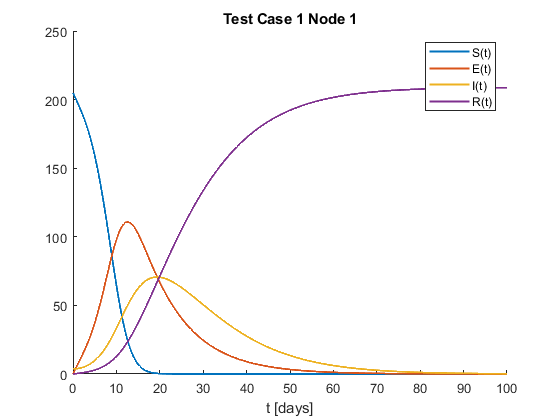

clc; clear; close all;
rng(1);
P = 1;              % # nodes simulated
t_start = 0;        % Start time (days)
t_stop = 100;       % End time (days)
timestep = 0.01;

% select input evaluation function
eval_u = 'GenInputVec';
% select model evaluation function
eval_f = 'EVALF';

theta = zeros(P,P);

% start state at time 0 equals input vector at time 0
x_start = GenInputVec(P, 0);
p = GenPStruct(P, theta);

% test FE function
[X] = ForwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);

%% Plot SEIR curves
S = X(1,:);
s = [S{1:end}];
N = sum(s, 1);
figure(1);
hold on;
days = linspace(t_start,t_stop,length(s(1,1:end)));
plot(days, s(1,1:end),  'LineWidth', 1.5);
xlabel('t [days]');

plot(days, s(2,1:end),  'LineWidth', 1.5);
xlabel('t [days]');

plot(days, s(3,1:end), 'LineWidth', 1.5);
xlabel('t [days]');

plot(days, s(4,1:end), 'LineWidth', 1.5);
xlabel('t [days]');
hold off;
legend('S(t)','E(t)','I(t)','R(t)');
title(['Test Case 1' ' Node ', num2str(1)])

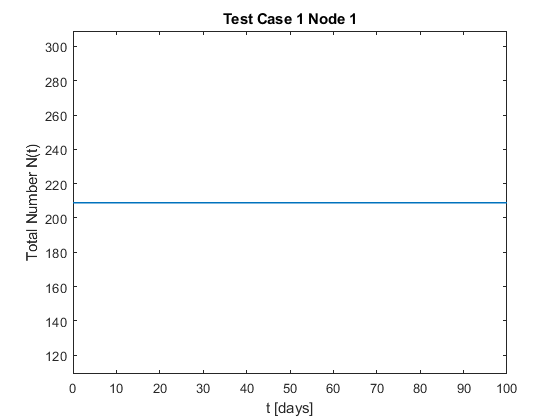


plot(days,N,'LineWidth',1.5);
ylim([max(N)-100, max(N)+100]);
xlabel('t [days]'); ylabel('Total Number N(t)');
title(['Test Case 1 Node ', num2str(1)])

#### Test Case 2: 10 Communities (No Inter-Node Transmission)

We expect to see SEIR curves for each node, but different depending on initial conditions.

clear; close all;
rng(1);
P = 10;    % # nodes simulated
t_start = 0;
t_stop = 60;
timestep = 0.01;

%select input evaluation function
eval_u = 'GenInputVec';
%select model evaluation function
eval_f = 'EVALF';

theta = zeros(P,P);

%start state at time 0 equals input vector at time 0
x_start = GenInputVec(P, 0);
p = GenPStruct(P, theta);

% test FE function
[X] = ForwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);

Qi = 0

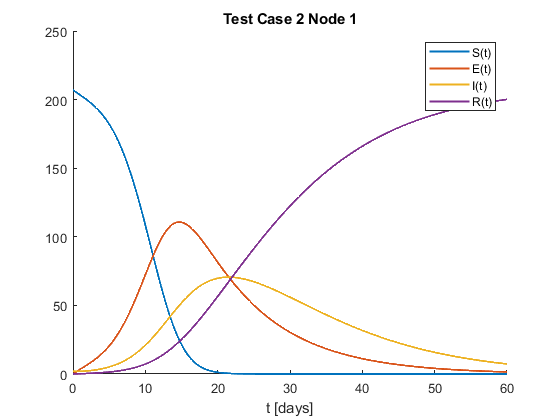

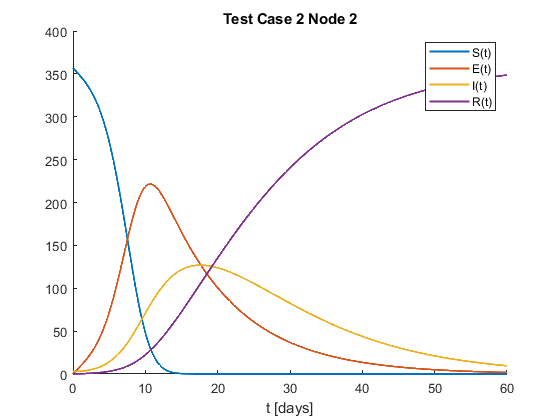

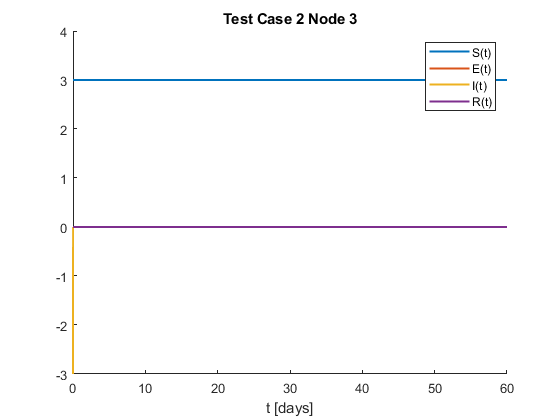

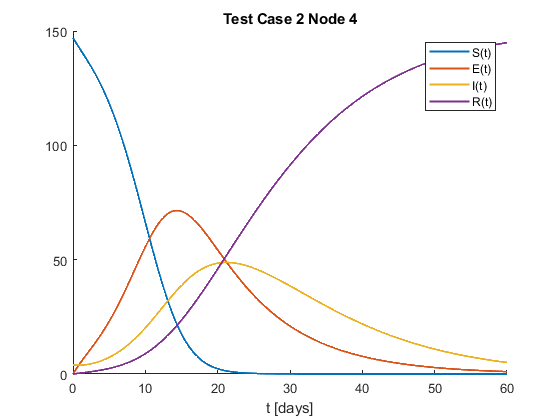

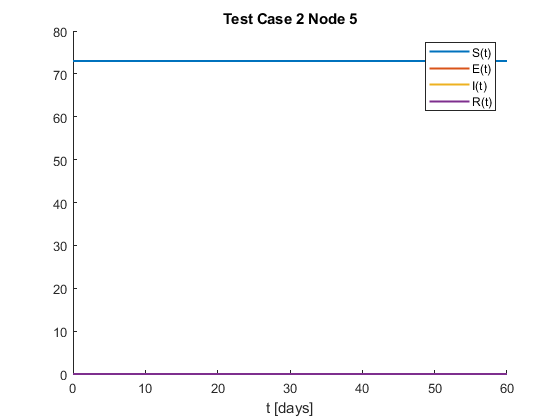

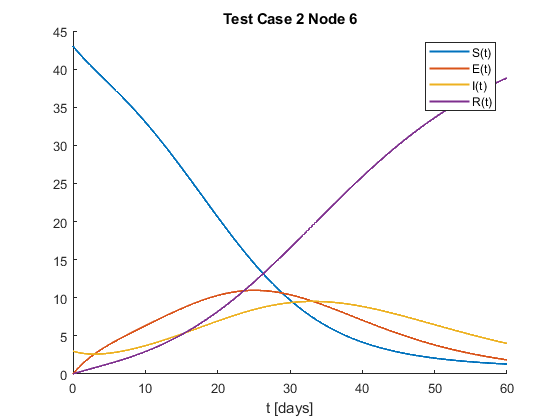

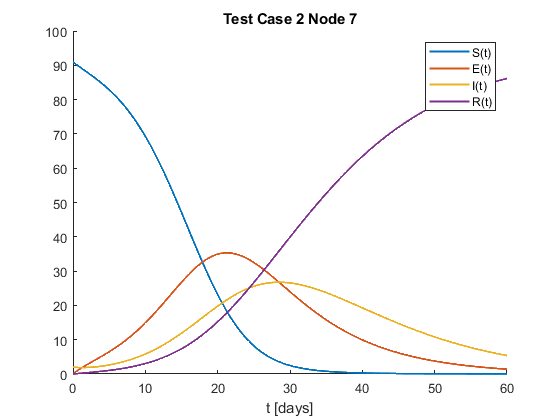

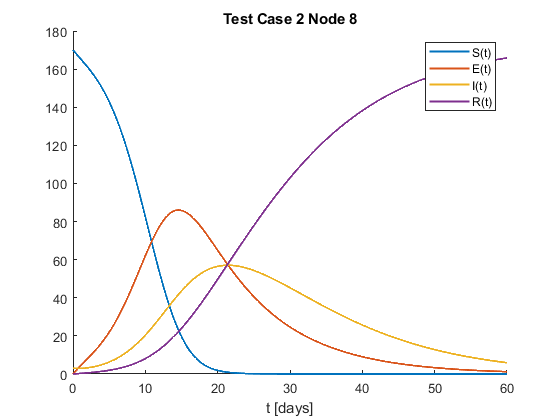


%% Plot SEIR curves for all nodes
for i = 1:size(X,1)
    S = X(i,:);
    s = [S{1:end}];
    N(i,:) = sum(s, 1);
    figure(i);
    hold on;
    days = linspace(t_start,t_stop,length(s(1,1:end)));
    plot(days, s(1,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, s(2,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, s(3,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, s(4,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    hold off;
    legend('S(t)','E(t)','I(t)','R(t)');
    title(['Test Case 2' ' Node ', num2str(i)])
end

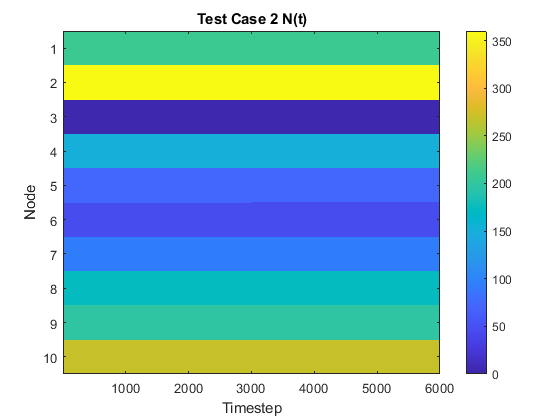


figure;
imagesc(N(:,:));
title('Test Case 2 N(t)');
xlabel('Timestep');
ylabel('Node');
colorbar;

#### Test Case 3: 20 Communities (No Inter-Node Transmission)

Scale-up by 2X. Takes longer, but should see similar results as previously.

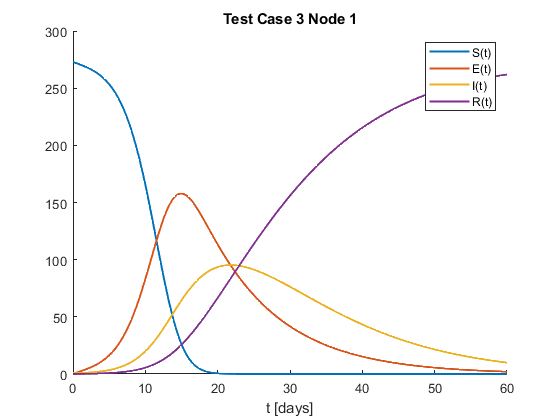

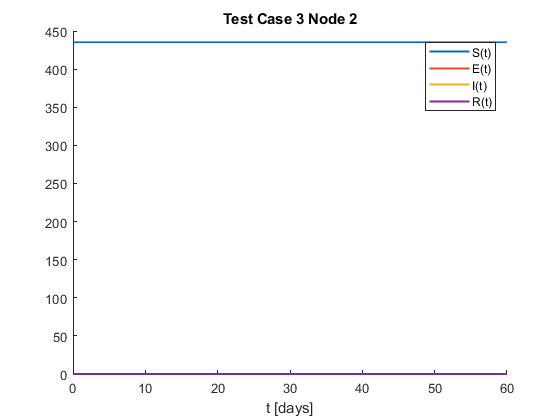

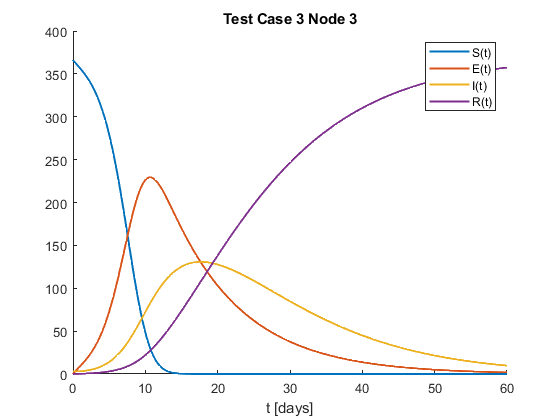

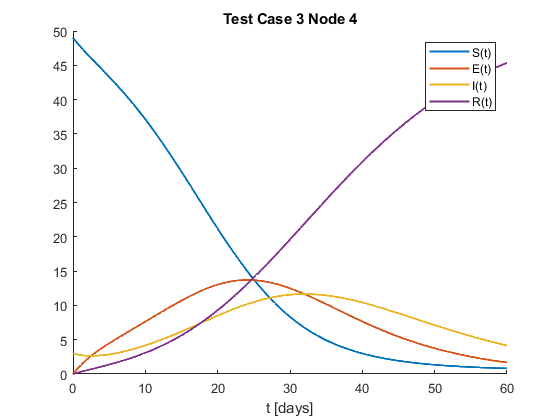

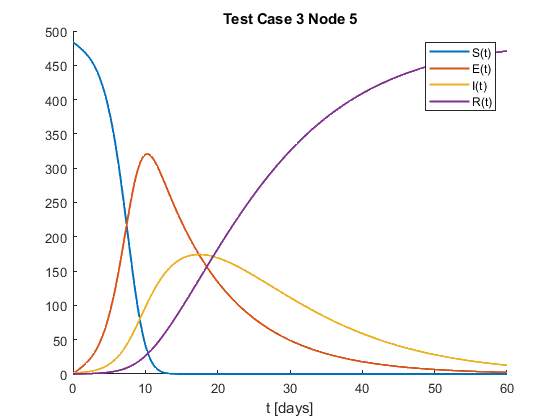

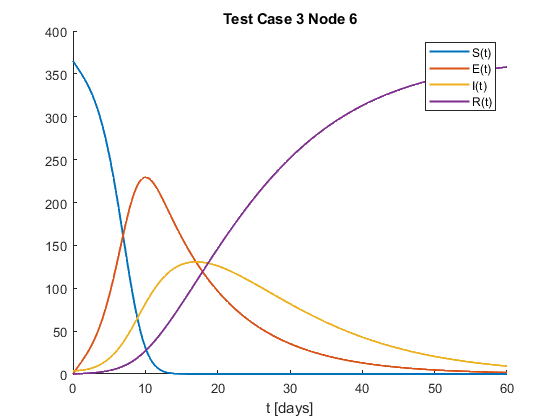

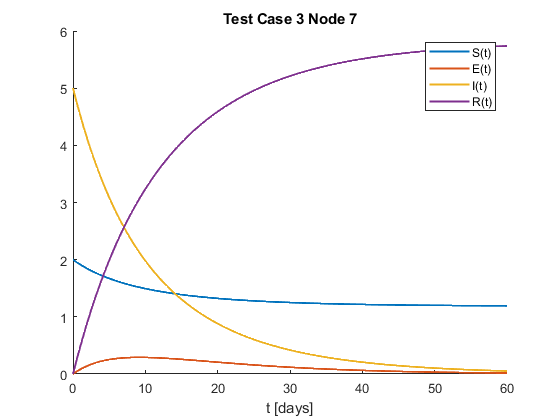

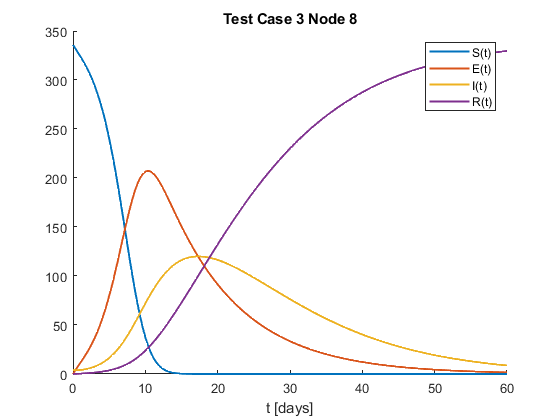

clear; close all;
P = 20;    % # nodes simulated
t_start = 0;
t_stop = 60;
timestep = 0.1;

%select input evaluation function
eval_u = 'GenInputVec';
%select model evaluation function
eval_f = 'EVALF';

theta = zeros(P,P);

%start state at time 0 equals input vector at time 0
x_start = GenInputVec(P, 0);
p = GenPStruct(P, theta);

% test FE function
[X] = ForwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);

%% Plot SEIR curves for all nodes
for i = 1:size(X,1)
    S = X(i,:);
    s = [S{1:end}];
    N(i,:) = sum(s, 1);
    figure(i);
    hold on;
    days = linspace(t_start,t_stop,length(s(1,1:end)));
    plot(days, s(1,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, s(2,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, s(3,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, s(4,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    hold off;
    legend('S(t)','E(t)','I(t)','R(t)');
    title(['Test Case 3' ' Node ', num2str(i)])
end

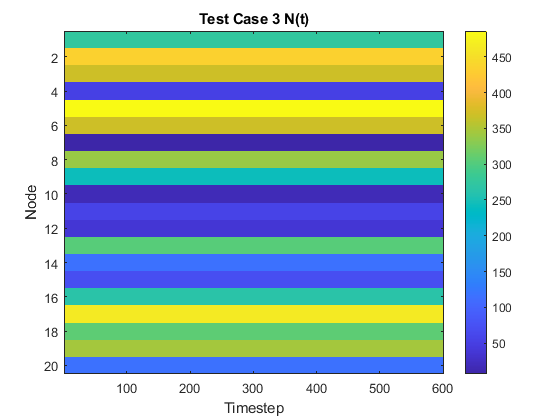


figure;
imagesc(N(:,:));
title('Test Case 3 N(t)');
xlabel('Timestep');
ylabel('Node');
colorbar;

#### Test Case 4: 10 Communities (Inter-Node Transmission)

Each node will have different SEIR curves since depending on initial conditions and theta parameters. 

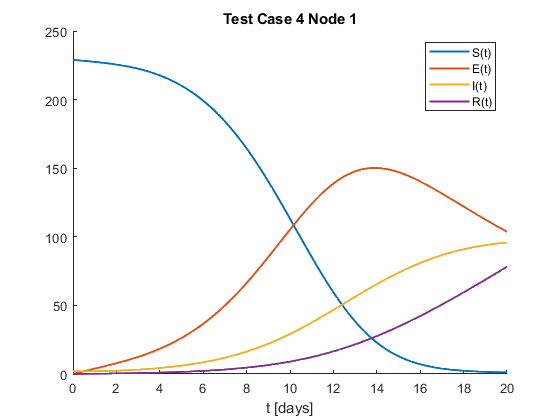

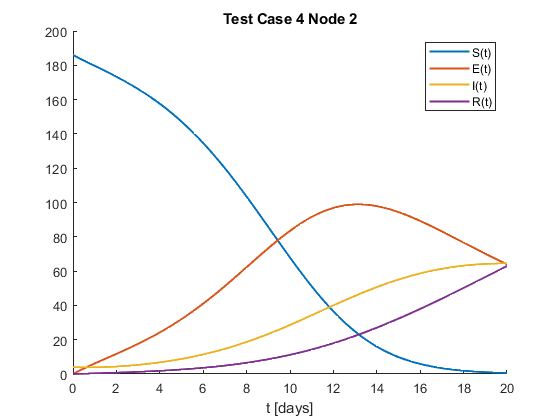

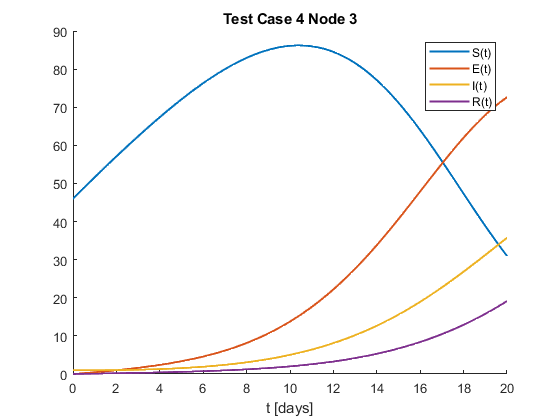

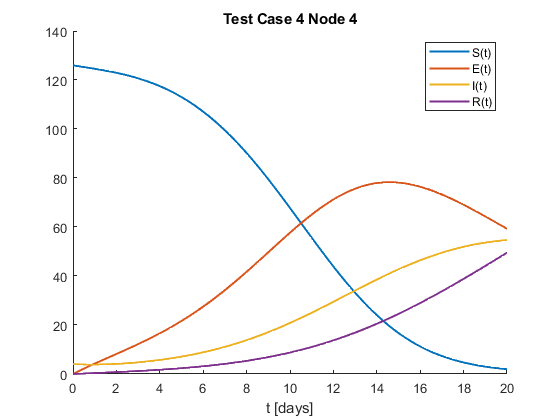

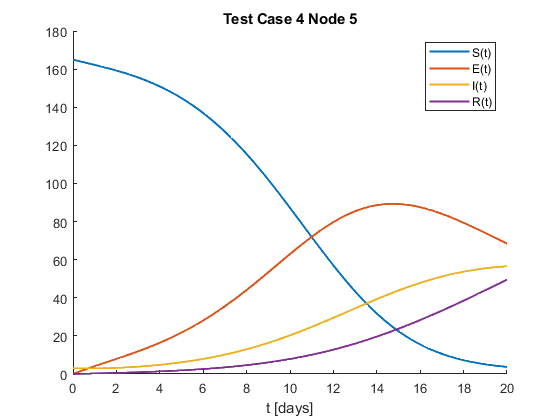

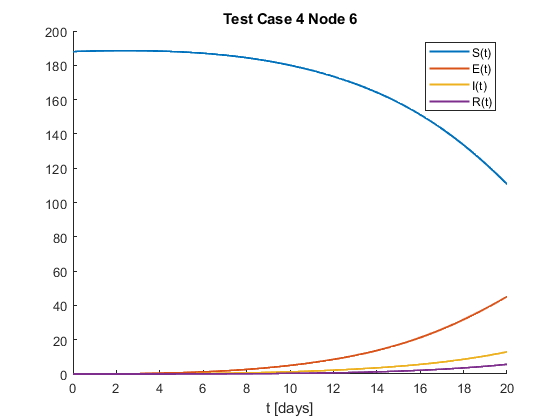

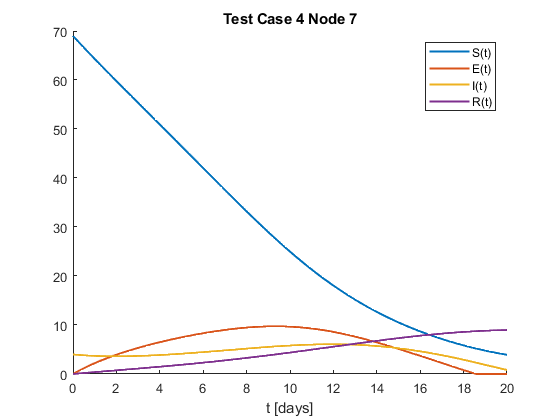

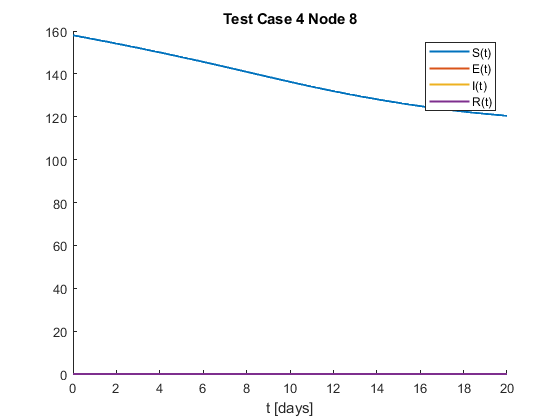

clear; close all;
P = 10;    % # nodes simulated
t_start = 0;
t_stop = 20;
timestep = 0.1;

%select input evaluation function
eval_u = 'GenInputVec';
%select model evaluation function
eval_f = 'EVALF';

theta = GenThetaMat(P,'symmetric');

%start state at time 0 equals input vector at time 0
x_start = GenInputVec(P, 0);
p = GenPStruct(P, theta);

% test FE function
[X] = ForwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);

% Plot SEIR curves for all nodes
for i = 1:size(X,1)
    S = X(i,:);
    s = [S{1:end}];
    N(i,:) = sum(s, 1);
    figure(i);
    hold on;
    days = linspace(t_start,t_stop,length(s(1,1:end)));
    plot(days, s(1,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, s(2,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, s(3,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, s(4,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    hold off;
    legend('S(t)','E(t)','I(t)','R(t)');
    title(['Test Case 4' ' Node ', num2str(i)])
end

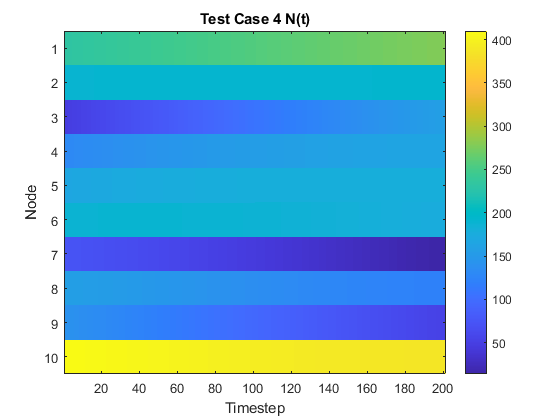


figure;
imagesc(N(:,:));
title('Test Case 4 N(t)');
xlabel('Timestep');
ylabel('Node');
colorbar;

#### Test Case 5: 10 Communities (No Input)

Expect zeros for all plots.

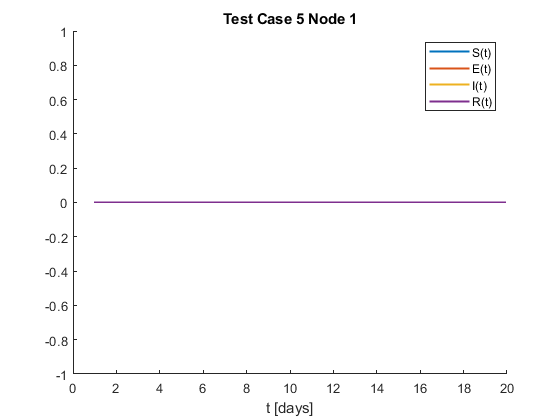

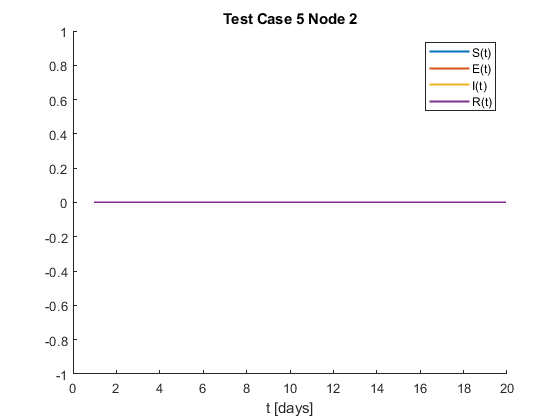

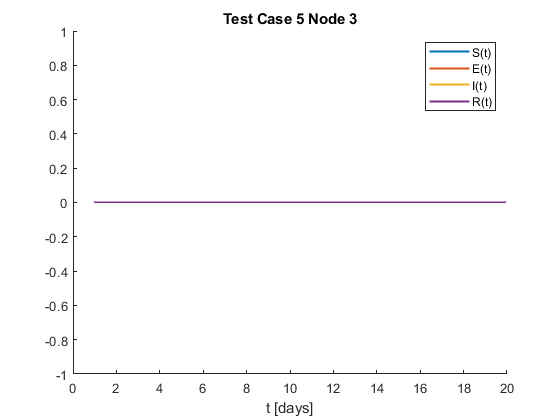

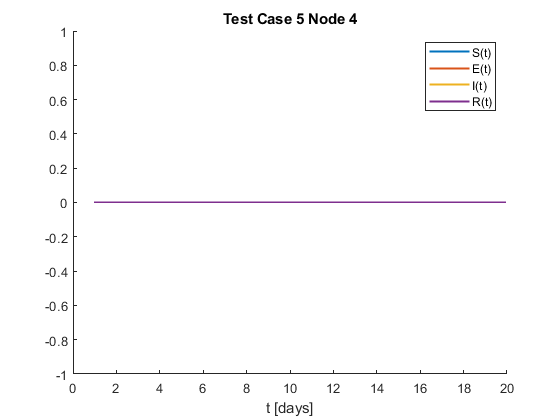

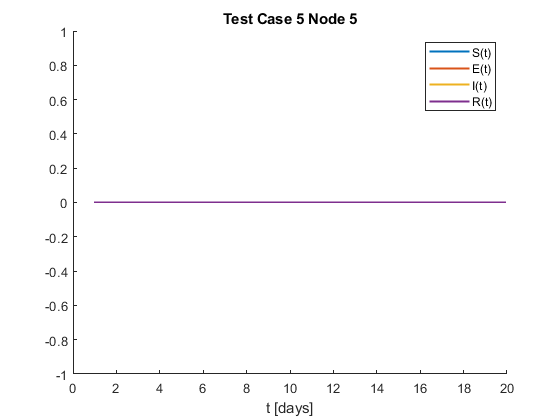

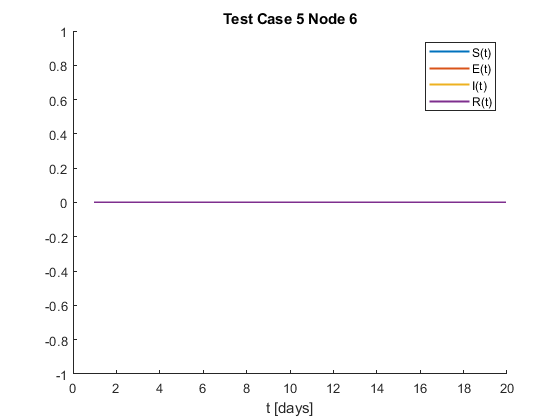

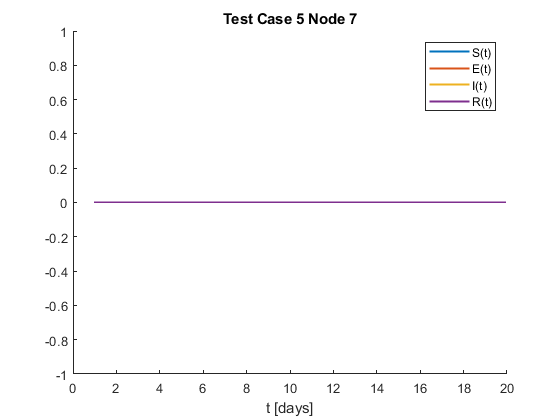

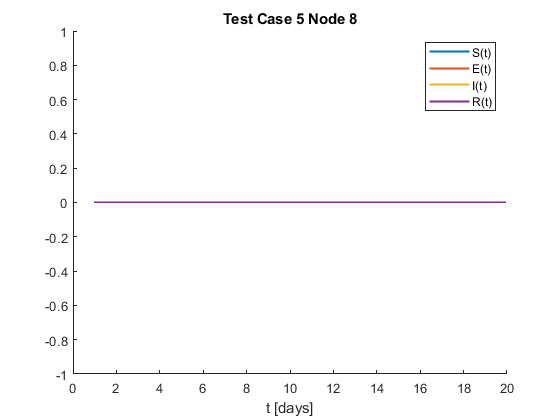

clear; close all;
P = 10;    % # nodes simulated
t_start = 1;
t_stop = 20;
timestep = 0.1;

%select input evaluation function
eval_u = 'GenInputVec';
%select model evaluation function
eval_f = 'EVALF';

theta = GenThetaMat(P,'symmetric');

%start state at time 0 equals input vector at time 0
x_start = GenStateVec(P, 'else');
p = GenPStruct(P, theta);

% test FE function
[X] = ForwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);

% Plot SEIR curves for all nodes
for i = 1:size(X,1)
    S = X(i,:);
    s = [S{1:end}];
    N(i,:) = sum(s, 1);
    figure(i);
    hold on;
    days = linspace(t_start,t_stop,length(s(1,1:end)));
    plot(days, s(1,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, s(2,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, s(3,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, s(4,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    hold off;
    legend('S(t)','E(t)','I(t)','R(t)');
    title(['Test Case 5' ' Node ', num2str(i)])
end

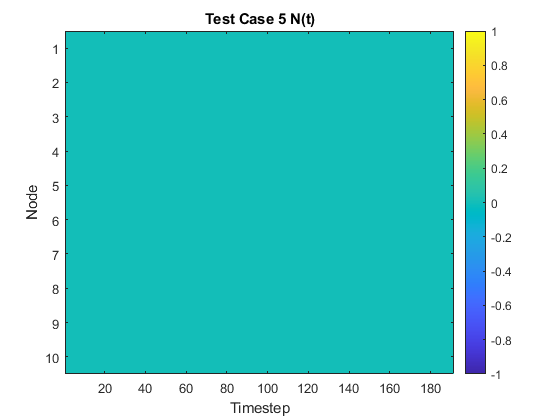

figure;
imagesc(N(:,:));
title('Test Case 5 N(t)');
xlabel('Timestep');
ylabel('Node');
colorbar;

#### Test Case 5: 10 Communities (Same Initial Conditions)

All SEIR curves should evolve similarly. Since $\theta \;$ is skew symmetric, we expect the total number of individuals in the system $\sum_i N_i \left(t\right)\;$to be constant.

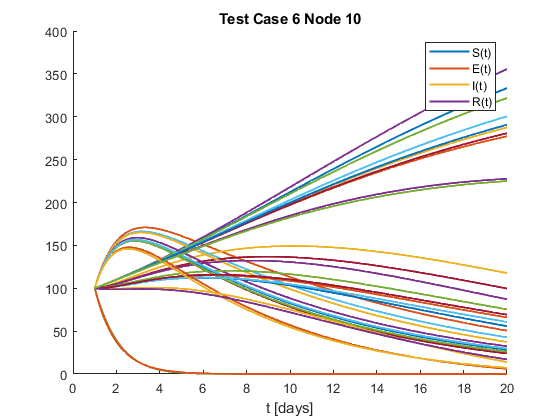

clear; close all;
P = 10;    % # nodes simulated
t_start = 1;
t_stop = 20;
timestep = 0.1;

%select input evaluation function
eval_u = 'GenInputVec';
%select model evaluation function
eval_f = 'EVALF';

theta = GenThetaMat(P,'symmetric');

%start state at time 0 equals input vector at time 0
x_start = GenStateVec(P, 'sameIC');
p = GenPStruct(P, theta);

% test FE function
[X] = ForwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);

% Plot SEIR curves for all nodes
for i = 1:size(X,1)
    S = X(i,:);
    s = [S{1:end}];
    N(i,:) = sum(s, 1);
    figure(1);
    hold on;
    days = linspace(t_start,t_stop,length(s(1,1:end)));
    plot(days, s(1,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, s(2,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, s(3,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, s(4,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    hold off;
    legend('S(t)','E(t)','I(t)','R(t)');
    title(['Test Case 6' ' Node ', num2str(i)])
end

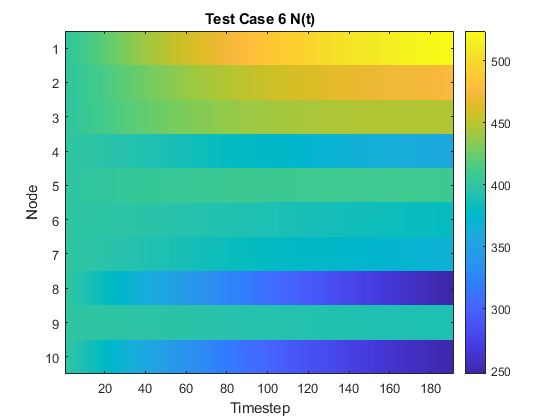

figure;
imagesc(N(:,:));
title('Test Case 6 N(t)');
xlabel('Timestep');
ylabel('Node');
colorbar;

For a skew-symmetric $\theta \;$matrix test case with the same starting input vector$x$ for all nodes, we expect the total number of individualds in the entire system to be constant. However, we see that it decreases slowly.

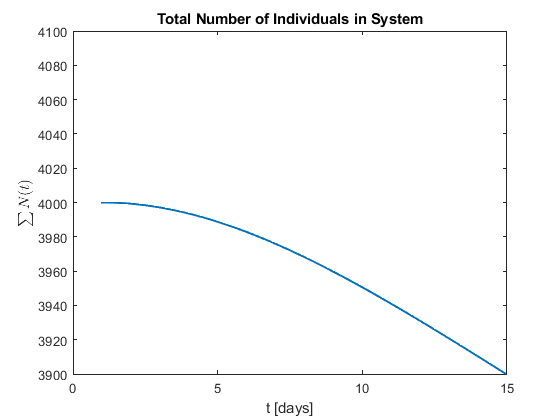

plot(days,sum(N,1),'LineWidth',1.5);
ylim([max(sum(N,1))-100, max(sum(N,1))+100]);
xlabel('t [days]'); ylabel('$\sum{N(t)}$','interpreter','latex');
title(['Total Number of Individuals in System'])

This could be due to round off error. The sum over all theta parameters

fprintf('Sum over all theta params %d\n', sum([p.theta]));

Sum over all theta params -1.970537e-17


is below our machine epsilon:

fprintf('Machine precision limit %d\n', eps);

Machine precision limit 2.220446e-16


Therefore, we expect that this drop in total number of individuals in the system is due to this small, but non-negligible loss of precision. Furthermore, the drop in number of people over time makes sense, because $\sum_i \;{\mathrm{dN}}_i /\mathrm{dt}=k$ where $k<0$ for equal starting conditions and a skew-symmetric $\theta \;$. So, we would expect to see a decrease in $\sum_i N_i \left(t\right)\;$vs. time. Note that individual nodes can increase, but the sum over all nodes should decrease.

## Future Tasks

- Re-write GenPStruct so it generates more varied/biologically relevant parameters

- Re-write GenThetaMat so $\theta {\;}^{\prime } s\;$is more physically relevant